clear all;
I=imread('2.jpg');
figure,
imshow(I);

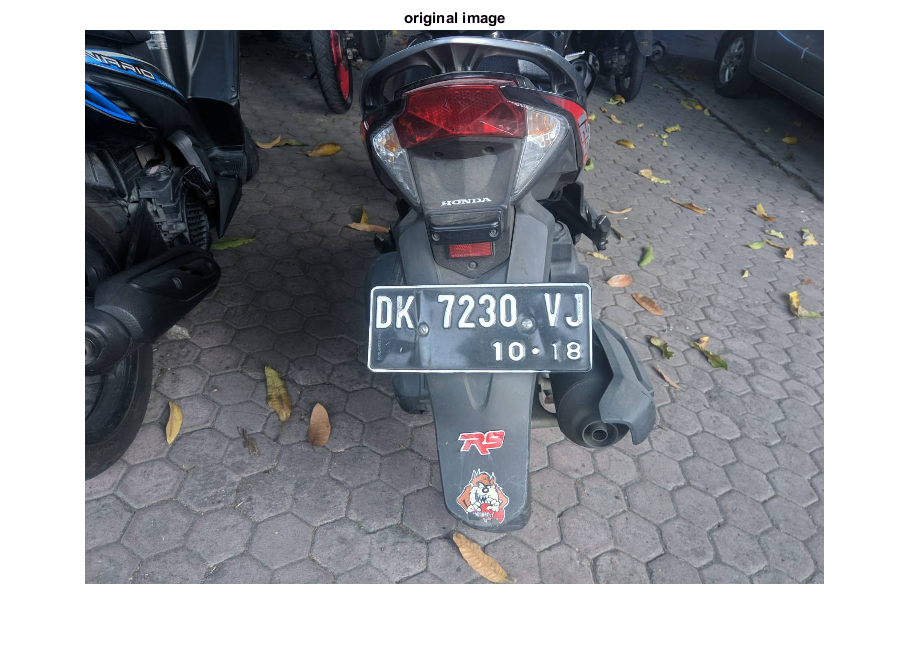

title('original image');

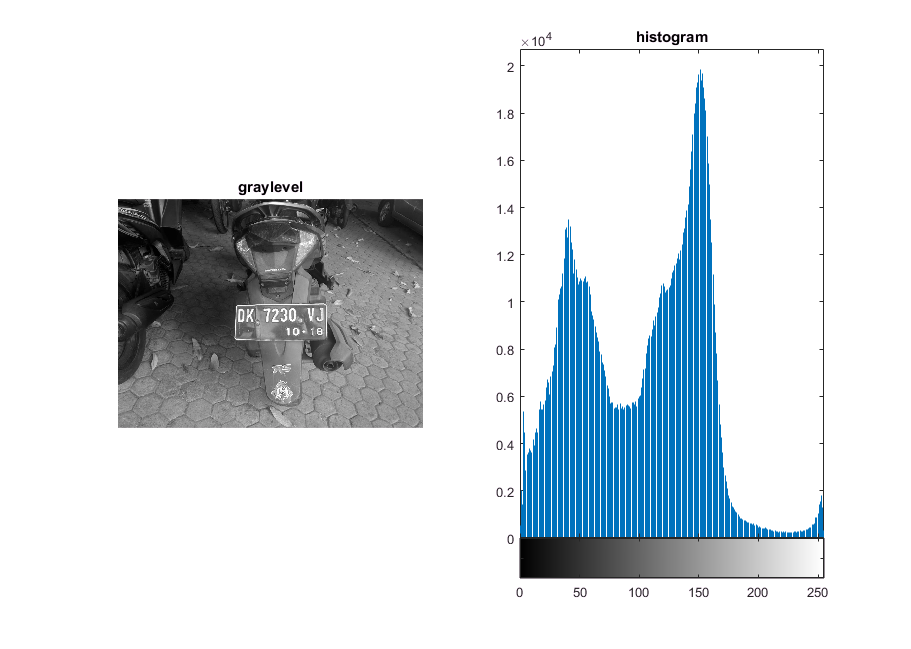

Im1 = rgb2gray(I); 
figure(2),
subplot(1,2,1),
imshow(Im1); 
title('graylevel');
figure(2),
subplot(1,2,2),
imhist(Im1);
title('histogram');

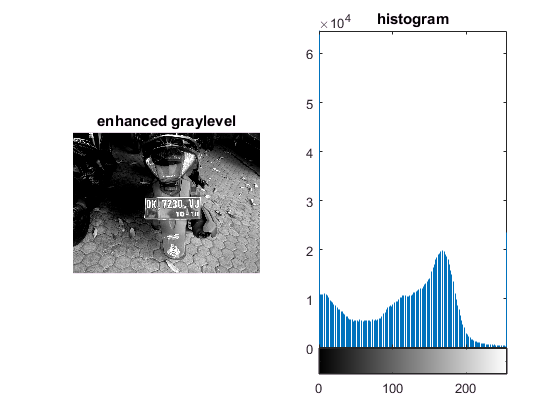

Im2 = imadjust(Im1,[0.2,0.8],[0,1]);
figure(3),
subplot(1,2,1),
imshow(Im2);
title('enhanced graylevel');
figure(3),
subplot(1,2,2),
imhist(Im2);
title('histogram');

se = [1;1;1];
Im4 = imerode(Im2,se);
figure(5),
imshow(Im4);

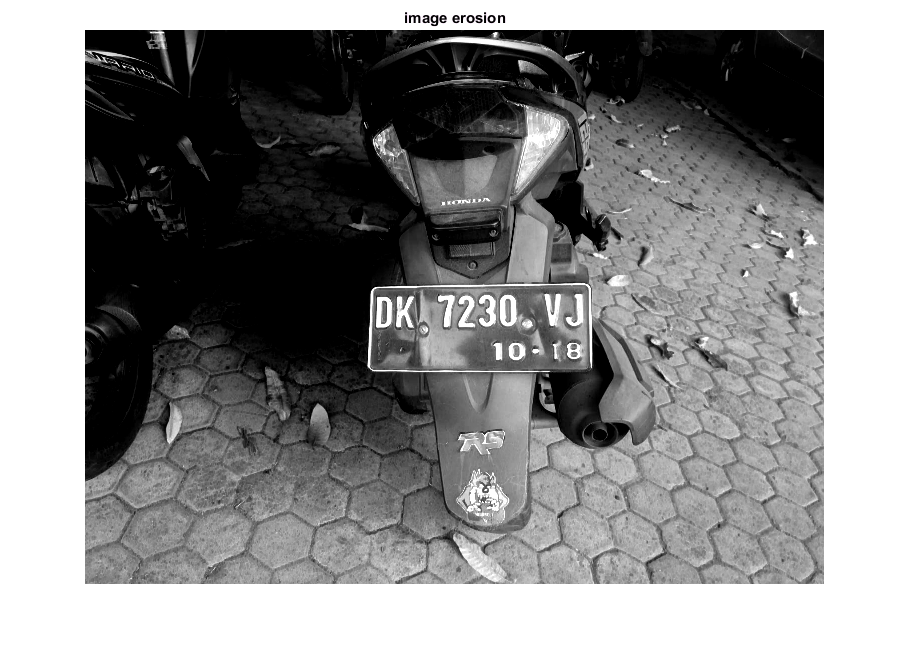

title('image erosion');

se = strel('rectangle',[25,25]);

Im5 = imclose(Im4,se);
figure(6),
imshow(Im5);

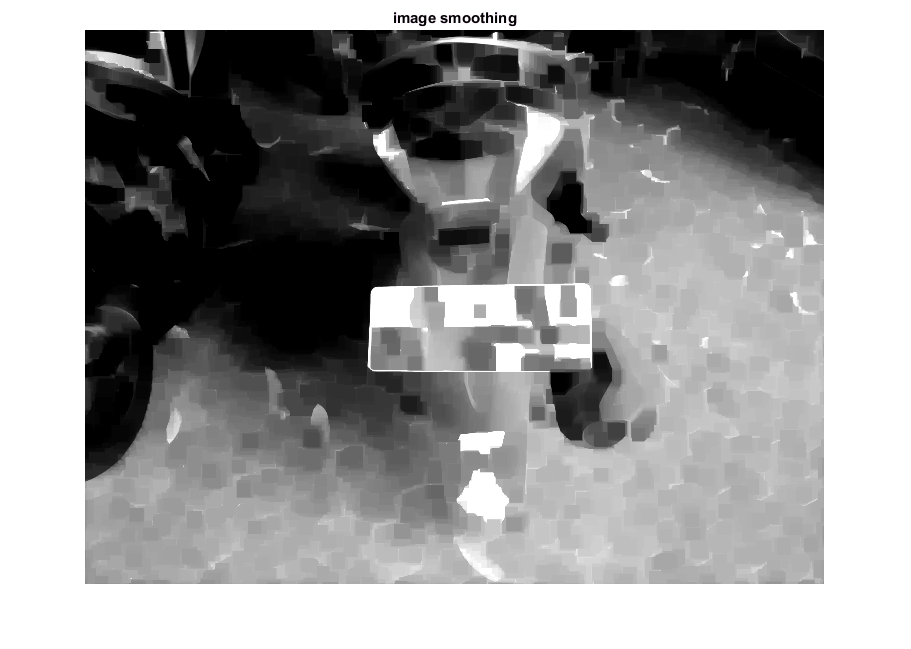

title('image smoothing');

Im6 = double((Im5)>220);               
Im6 = bwareaopen(Im6,2000);
se = strel('rectangle',[5,5]);
Im6 = imdilate(Im6,se);
figure(7),
imshow(Im6);

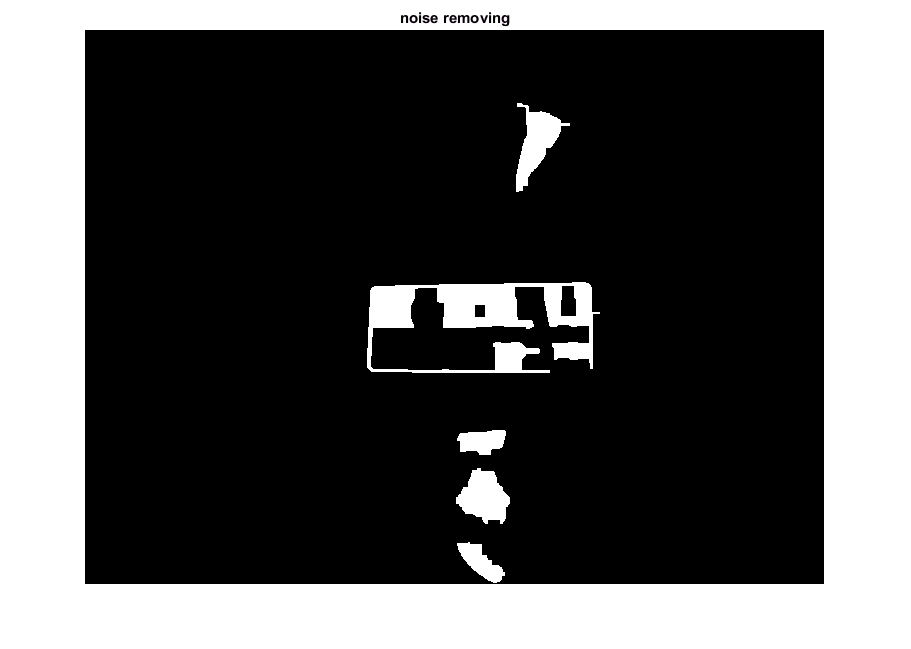

title('noise removing');

S = regionprops(Im6,'BoundingBox', 'ConvexArea', 'Eccentricity', 'Area');
[~,idx]=sort([S.Area]);
S=S(idx);

figure(7),
imshow(Im6);

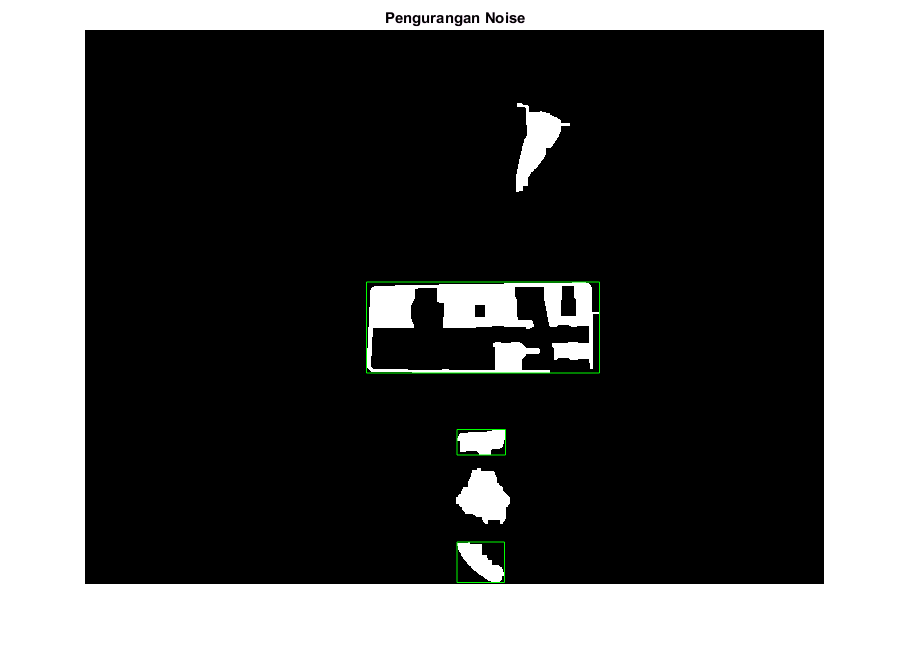

title('Pengurangan Noise');
 
hold on ; %tetap mengaktifan figur citra biner di atas
for i=1:size(S,1)
    if ((S(i).BoundingBox(3)>S(i).BoundingBox(4))&&(S(i).Eccentricity>=0.8700)&&(S(i).Eccentricity<=0.9550))
        rectangle('Position', S(i).BoundingBox,'edgecolor','green');
        Plat = S(i).BoundingBox;
    end
end

siz=size(Im6);
Plat_x=[Plat(1)+5 Plat(1)+Plat(3)-5];
Plat_y=[Plat(2)+5 Plat(2)+Plat(4)-5];
if Plat_x(1)<1, Plat_x(1)=1; end
if Plat_y(1)<1, Plat_y(1)=1; end
if Plat_x(2)>siz(2), Plat_x(2)=siz(2); end
if Plat_y(2)>siz(1), Plat_y(2)=siz(1); end

im=Im1;
hasil=im(Plat_y(1):Plat_y(2),Plat_x(1):Plat_x(2));

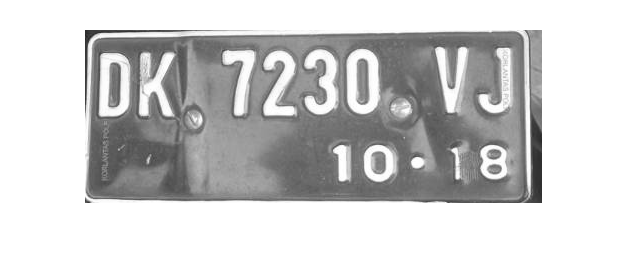


figure,
imshow(hasil);

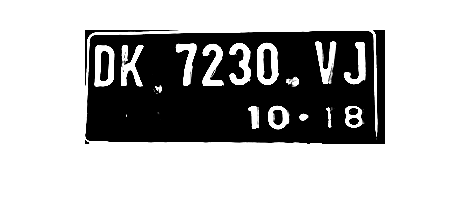

hasil = imresize(hasil, [NaN 300]);
tes = imadjust(hasil,[0.7 0.8],[]);
figure,
imshow(tes);

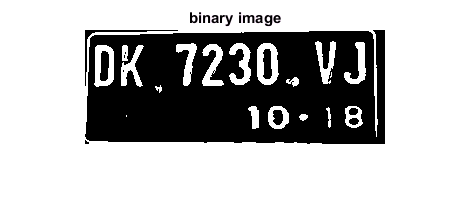

b = tes;
g_max = double(max(max(b)));
g_min = double(min(min(b)));
T = round(g_max-(g_max-g_min)/3);

d = double((b)>=T);

figure,

imshow(d),
title('binary image');

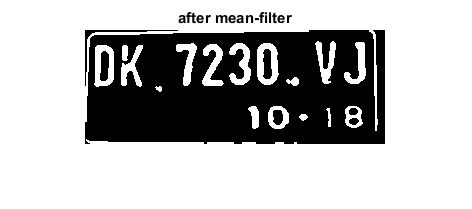

h = fspecial('average',3);
d = imbinarize(round(filter2(h,d)));
figure,
imshow(d),
title('after mean-filter');

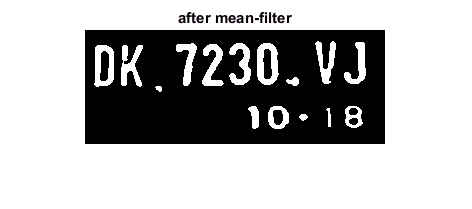

h = fspecial('average',3);
d = imclearborder(d, 4);
d = bwmorph(d,'close');
figure,
imshow(d),
title('after mean-filter');

%se = strel('rectangle',[2,2]);
%erosi = imerode(d,se);
%figure,
%imshow(erosi),
%title('after mean-filter');

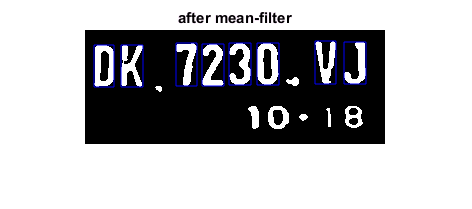

char = regionprops(d,'BoundingBox', 'Area', 'Eccentricity','Centroid');

figure;
imshow(d),
title('after mean-filter');
hold on ; %tetap mengaktifan figur citra biner di atas

for i=1:size(char,1)
    %tes(i) = char(i).Eccentricity;
    if (char(i).Area>=235)&&(char(i).Eccentricity>=0.800)&&(char(i).Eccentricity<=0.990)
    %cfix{i} = char(i).BoundingBox;
    rectangle('Position', char(i).BoundingBox,'edgecolor','blue');
    end
end

%rectangle('Position', char(33).BoundingBox,'edgecolor','red');

perlu clustering centroid dengan mencari centroid yg memiliki jarak sejajar

generationID = 2;
L=bwlabel(d,8);
siz=size(d);
n=max(L(:)); % number of objects
ObjCell=cell(n,1);
imageId = 1;
z = 1;
for i=1:n
      % Get the bb of the i-th object and offest by 2 pixels in all
      % directions
      char_i=ceil(char(i).BoundingBox);
      char_x=[char_i(1)-2 char_i(1)+char_i(3)+2];
      char_y=[char_i(2)-2 char_i(2)+char_i(4)+2];
      if char_x(1)<1, char_x(1)=1; end
      if char_y(1)<1, char_y(1)=1; end
      if char_x(2)>siz(2), char_x(2)=siz(2); end
      if char_y(2)>siz(1), char_y(2)=siz(1); end
      % Crop the object and write to ObjCell
      imchar=L==i;
      charfix{i}=imchar(char_y(1):char_y(2),char_x(1):char_x(2));
      
      if (char(i).Area<=2100)&&(char(i).Area>=235)&&(char(i).Eccentricity>=0.800)&&(char(i).Eccentricity<=0.990)
          img = imresize(charfix{i},[32, 16]);
          %img = bwmorph(img, 'thin', 'inf');
          imwrite(img, ['dataset/' num2str(generationID,'%d') '_' num2str(z,'%d') '.bmp'], 'bmp');
          imageId = imageId + 1;
          cf{i} = charfix{i};
          z = z +1;
      end
end

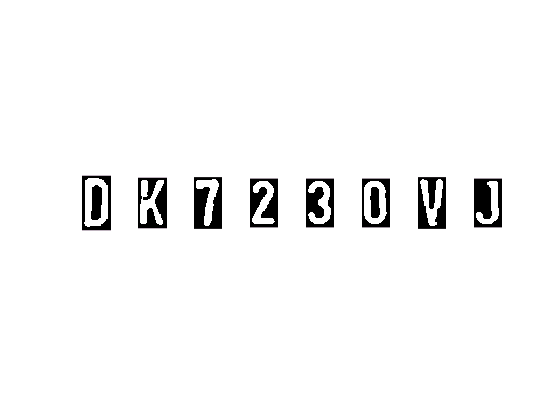

cf = cf(~cellfun(@isempty, cf));
p=length(cf);
figure
for j=1:p
    subplot(1,p,j)
    imshow(cf{j})
end

load templates
global templates

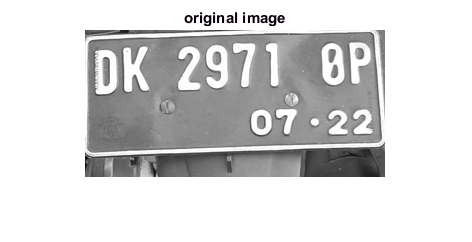

for flag2=1:p
    n2=imread(strcat('dataset\',num2str(generationID,'%d'),'_',num2str(flag2),'.bmp'));
    img_r=imresize(n2,[32 16]);
    letter=read_letter(img_r,36);
    result(flag2)=letter;
end
figure(11)
imshow(hasil);
title('original image');

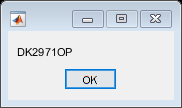

msgbox(result)